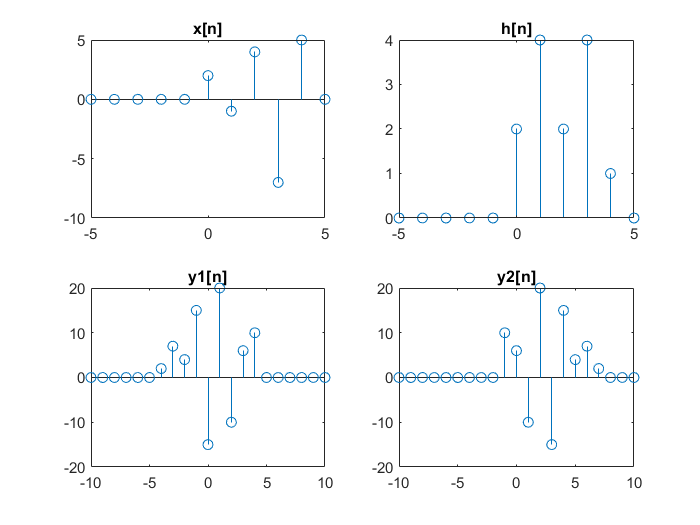

clc 
clear 
close all

m=5;
p=-m:1:m;
x=zeros(size(p));
x1=func7(p);subplot(2,2,1);stem(p,x1);title('x[n]');
h1=func8(p);subplot(2,2,2);stem(p,h1);title('h[n]');
h2=func8(-p);
y1=conv(x1,h2);
n=-2*m:1:2*m;
subplot(2,2,3);stem(n,y1);title('y1[n]');
x2=func7(3-p);
y2=conv(x2,h1);
subplot(2,2,4);stem(n,y2);title('y2[n]');